clear all;
addpath('E:\学\大二上\信号\lab\proj2\data');
addpath("E:\学\大二上\信号\lab\proj2")
for idx_start_time = 1 : 20
load(sprintf('data/data_%d.mat',idx_start_time));

%raw时域图

N = length(seq_ref);
n = 0 : length(seq_ref) - 1;
t = n / f_s;
% t = linspace(0, duration, length(seq_ref));

%raw频域图
% ref_fft = fft(seq_ref) / length(seq_ref);
ref_fft = fft(seq_ref, N);
ref_fft_shift = fftshift(ref_fft);

sur_fft = fft(seq_sur, N);
sur_fft_shift = fftshift(sur_fft);

%DDC
%时域
f_mid = 3e6 * 2 * pi;
ref_shift = seq_ref .* exp(j * f_mid * t);
sur_shift = seq_sur .* exp(j * f_mid * t);

%频域
%shift之后要不要转回频域做滤波
ref_shift_fft = fft(ref_shift, N);
ref_shift_fft_shift = fftshift(ref_shift_fft);

sur_shift_fft = fft(sur_shift, N);
sur_shift_fft_shift = fftshift(sur_shift_fft);

%低通
% 找低通滤波器系数
[b_low, a_low] = butter(20, 9e6/(f_s/2));

% 找单位频率响应
ref_shift_LP = filter(b_low,a_low,ref_shift); %滤的时候是输入时频上的信号？？
sur_shift_LP = filter(b_low,a_low,sur_shift); 

%频域
ref_shift_LP_fft = fft(ref_shift_LP, N);
ref_shift_LP_fft_shift = fftshift(ref_shift_LP_fft);

sur_shift_LP_fft = fft(sur_shift_LP, N);
sur_shift_LP_fft_shift = fftshift(sur_shift_LP_fft);

figure(1);
myPlot(t, seq_ref, ref_fft_shift, "Reference", "raw", 1, f_s);
myPlot(t, ref_shift, ref_shift_fft_shift, "Reference", "DDC", 3, f_s);
myPlot(t, ref_shift_LP, ref_shift_LP_fft_shift, "Reference", "LPF", 5, f_s);
adressString = ['E:\学\大二上\信号\lab\proj2\pic\',sprintf('%d reference', idx_start_time), '.jpg']

adressString = 'E:\学\大二上\信号\lab\proj2\pic\1 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\2 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\3 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\4 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\5 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\6 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\7 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\8 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\9 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\10 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\11 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\12 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\13 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\14 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\15 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\16 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\17 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\18 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\19 reference.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\20 reference.jpg'

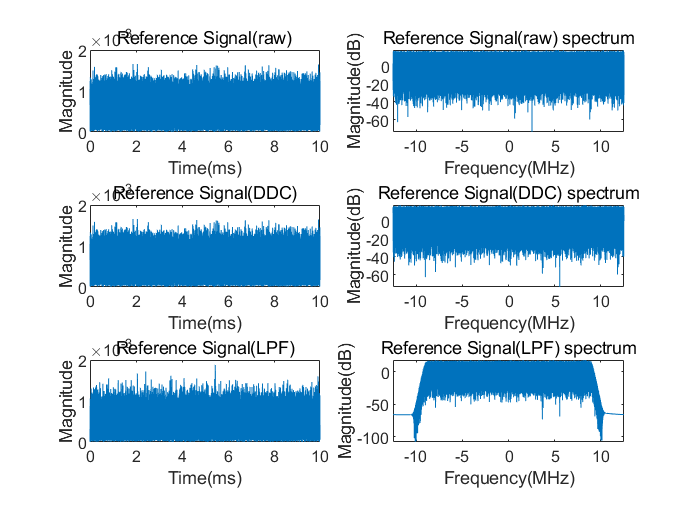

saveas(1, adressString);

figure(2);
myPlot(t, seq_sur, sur_fft_shift, "Surveillance", "raw", 1, f_s);
myPlot(t, sur_shift, sur_shift_fft_shift, "Surveillance", "DDC", 3, f_s);
myPlot(t, sur_shift_LP, sur_shift_LP_fft_shift, "Surveillance", "LPF", 5, f_s);
adressString = ['E:\学\大二上\信号\lab\proj2\pic\',sprintf('%d surveillance', idx_start_time), '.jpg']

adressString = 'E:\学\大二上\信号\lab\proj2\pic\1 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\2 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\3 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\4 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\5 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\6 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\7 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\8 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\9 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\10 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\11 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\12 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\13 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\14 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\15 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\16 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\17 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\18 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\19 surveillance.jpg'

adressString = 'E:\学\大二上\信号\lab\proj2\pic\20 surveillance.jpg'

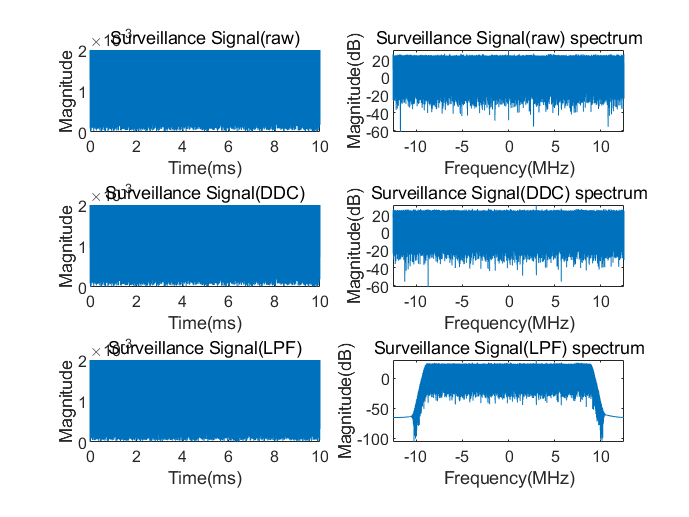

saveas(2, adressString);

end
